Load in the data, which contains  

- min_energies : num_graphs rows, num_trials columns 

- tts

# 200 node plots (100 graphs)

network is trained on 200 node plots

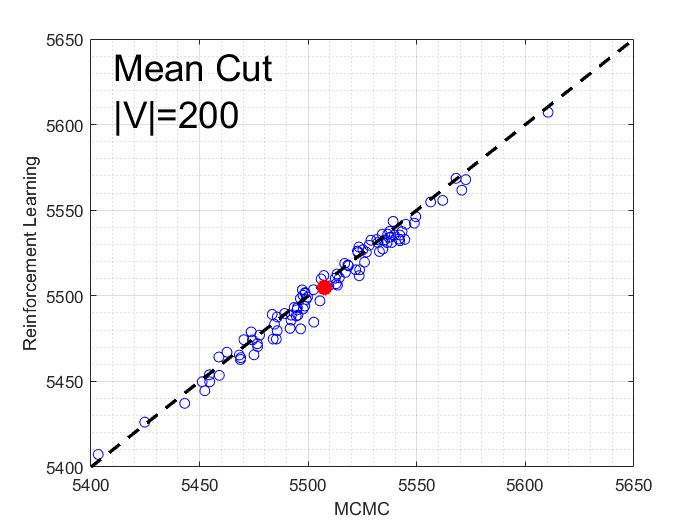


clearvars
load("sfm_100graphs_200nodes_15runs_1e5prop.mat")
min_energies = min_energies * -1;
mean_vals_sfm = mean(min_energies, 2);
plus_std_sfm = mean_vals_sfm + std(min_energies,0,2);
minus_std_sfm = mean_vals_sfm - std(min_energies,0,2);
min_vals_sfm = min(min_energies, [], 2);

load("rl_100graphs_200nodes_15runs.mat")
mean_vals_rl = mean(min_energies, 2);
plus_std_rl = mean_vals_rl + std(min_energies,0,2);
minus_std_rl = mean_vals_rl - std(min_energies,0,2);
min_vals_rl = min(min_energies, [], 2);


figure
grid on
grid minor
hold on
box on
scatter(mean_vals_sfm, mean_vals_rl,'b')
plot([5400:1:5650],[5400:1:5650], 'k--', 'linewidth', 2)
xlabel('MCMC')
ylabel('Reinforcement Learning')
str = {'Mean Cut','|V|=200'};
text(5410, 5620, str, 'FontSize', 22);
x = mean(mean_vals_sfm);
y = mean(mean_vals_rl);
scatter(x, y, 'r*', 'linewidth',8)
hold off

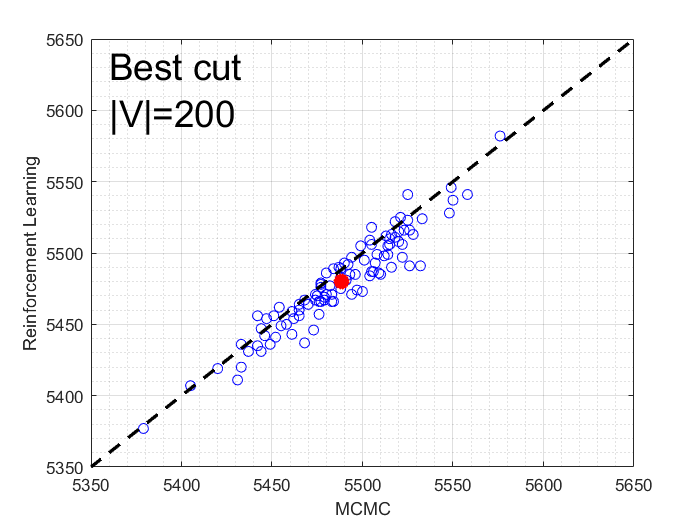


figure
grid on
grid minor
hold on
box on
scatter(min_vals_sfm, min_vals_rl,'b')
plot([5350:1:5650],[5350:1:5650], 'k--', 'linewidth', 2)
xlabel('MCMC')
ylabel('Reinforcement Learning')
str = {'Best cut','|V|=200'};
text(5360, 5615, str, 'FontSize', 22);
x = mean(min_vals_sfm);
y = mean(min_vals_rl);
scatter(x, y, 'r*', 'linewidth',8)
hold off

# 300 node plots (20 graphs)

network trained on 200 node plots

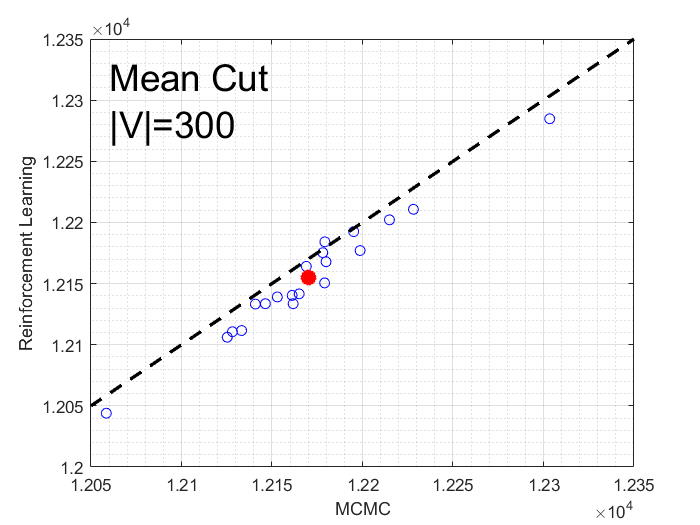


clearvars
load("sfm_20graphs_300nodes_15runs_1e5prop.mat")
min_energies = min_energies * -1;
mean_vals_sfm = mean(min_energies, 2);
plus_std_sfm = mean_vals_sfm + std(min_energies,0,2);
minus_std_sfm = mean_vals_sfm - std(min_energies,0,2);
min_vals_sfm = min(min_energies, [], 2);

load("rl_20graphs_300nodes_15runs.mat")
mean_vals_rl = mean(min_energies, 2);
plus_std_rl = mean_vals_rl + std(min_energies,0,2);
minus_std_rl = mean_vals_rl - std(min_energies,0,2);
min_vals_rl = min(min_energies, [], 2);

figure
grid on
grid minor
hold on
box on
scatter(mean_vals_sfm, mean_vals_rl,'b')
s = 12050;
f = 12350;
plot([s:1:f],[s:1:f], 'k--', 'linewidth', 2)
xlabel('MCMC')
ylabel('Reinforcement Learning')
str = {'Mean Cut','|V|=300'};
text(12060, 12300, str, 'FontSize', 22);
x = mean(mean_vals_sfm);
y = mean(mean_vals_rl);
scatter(x, y, 'r*', 'linewidth',8)
hold off

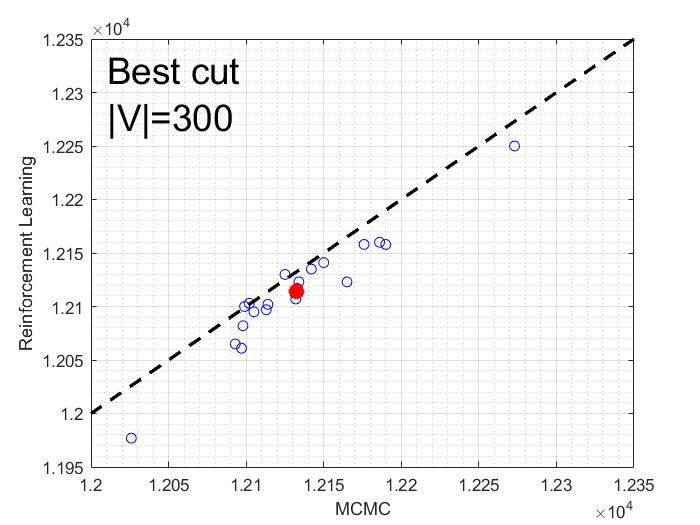


figure
grid on
grid minor
hold on
box on
scatter(min_vals_sfm, min_vals_rl,'b')
s = 12000;
f = 12350;
plot([s:1:f],[s:1:f], 'k--', 'linewidth', 2)
xlabel('MCMC')
ylabel('Reinforcement Learning')
str = {'Best cut','|V|=300'};
text(12010, 12300, str, 'FontSize', 22);
x = mean(min_vals_sfm);
y = mean(min_vals_rl);
scatter(x, y, 'r*', 'linewidth',8)

hold off

# 400 node plots (10 graphs)

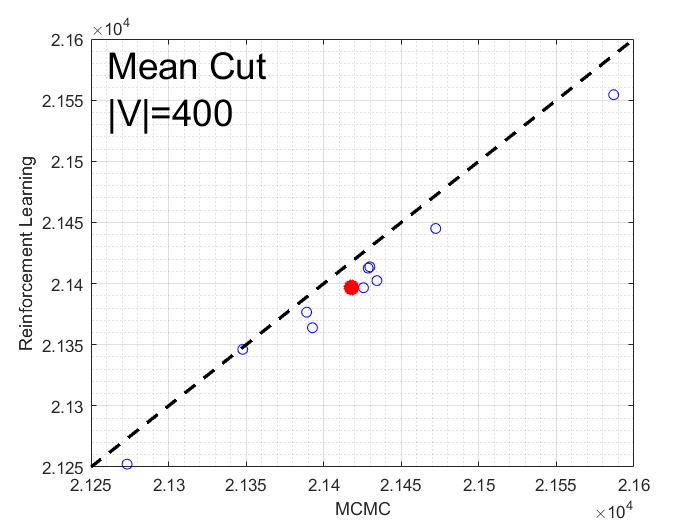


clearvars
load("sfm_10graphs_400nodes_15runs_1e5prop.mat")
min_energies = min_energies * -1;
mean_vals_sfm = mean(min_energies, 2);
plus_std_sfm = mean_vals_sfm + std(min_energies,0,2);
minus_std_sfm = mean_vals_sfm - std(min_energies,0,2);
min_vals_sfm = min(min_energies, [], 2);

load("rl_10graphs_400nodes_15runs.mat")
mean_vals_rl = mean(min_energies, 2);
plus_std_rl = mean_vals_rl + std(min_energies,0,2);
minus_std_rl = mean_vals_rl - std(min_energies,0,2);
min_vals_rl = min(min_energies, [], 2);

figure
grid on
grid minor
hold on
box on
scatter(mean_vals_sfm, mean_vals_rl,'b')
s = 21250;
f = 21600;
plot([s:1:f],[s:1:f], 'k--', 'linewidth', 2)
xlabel('MCMC')
ylabel('Reinforcement Learning')
str = {'Mean Cut','|V|=400'};
text(21260, 21560, str, 'FontSize', 22);
x = mean(mean_vals_sfm);
y = mean(mean_vals_rl);
scatter(x, y, 'r*', 'linewidth',8)
hold off

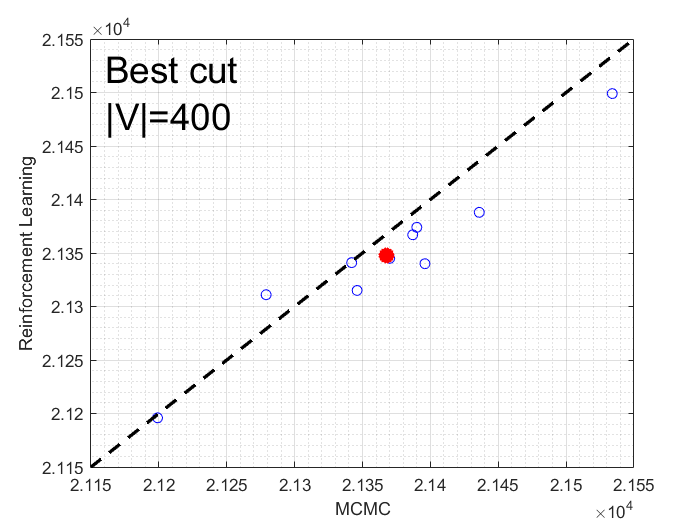


figure
grid on
grid minor
hold on
box on
scatter(min_vals_sfm, min_vals_rl,'b')
s = 21150;
f = 21550;
plot([s:1:f],[s:1:f], 'k--', 'linewidth', 2)
xlabel('MCMC')
ylabel('Reinforcement Learning')
str = {'Best cut','|V|=400'};
text(21160, 21500, str, 'FontSize', 22);
x = mean(min_vals_sfm);
y = mean(min_vals_rl);
scatter(x, y, 'r*', 'linewidth',8)

hold off

# Size 200,300 variance comparison

100 runs per graph for 1 graph of each size, compare how variance in the minimum cut changes per run to know the precision of each approach. Does the MCMC approach consistently give better results? Or is it a lucky cut?

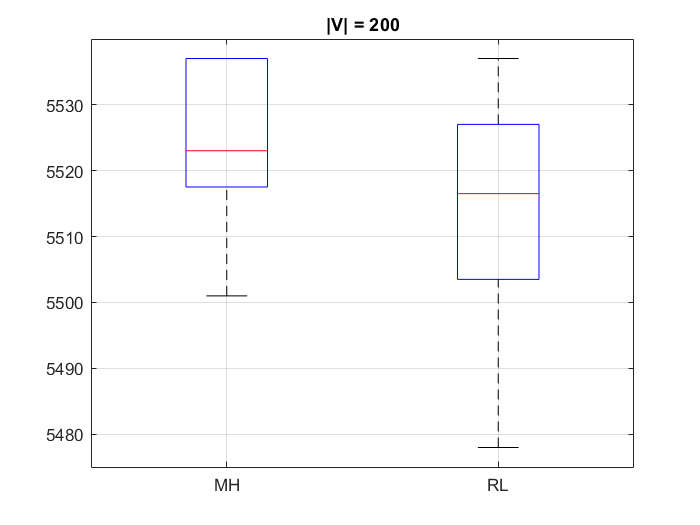

clearvars
load("sfm_1graphs_200nodes_100runs_1e6prop.mat")
min_energies = min_energies * -1;
min_energies_sfm = min_energies;
load("rl_1graphs_200nodes_100runs.mat")
sfm = min_energies_sfm(1,:).';
rl = min_energies(1,:).';
figure
boxplot([sfm rl], 'Labels', {'MH', 'RL'}, 'Whisker',10000)
title('|V| = 200')
grid on

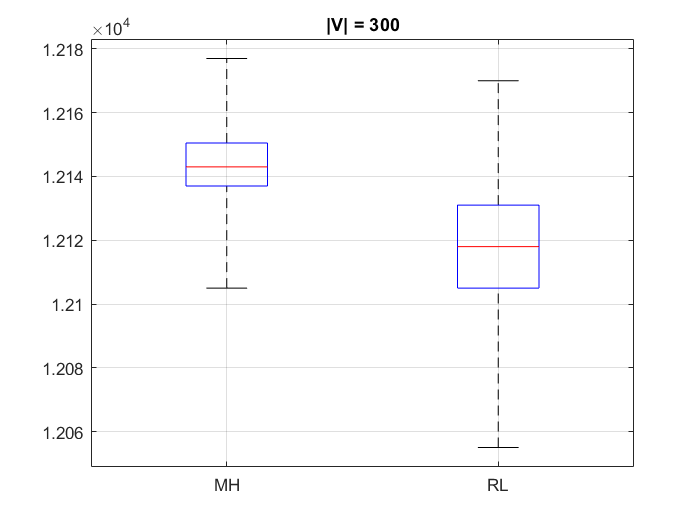


load("sfm_1graphs_300nodes_100runs_5e5prop.mat")
min_energies = min_energies * -1;
min_energies_sfm = min_energies;
load("rl_1graphs_300nodes_100runs.mat")
sfm = min_energies_sfm(1,:).';
rl = min_energies(1,:).';
figure
boxplot([sfm rl], 'Labels', {'MH', 'RL'}, 'Whisker',10000)
title('|V| = 300')
grid on

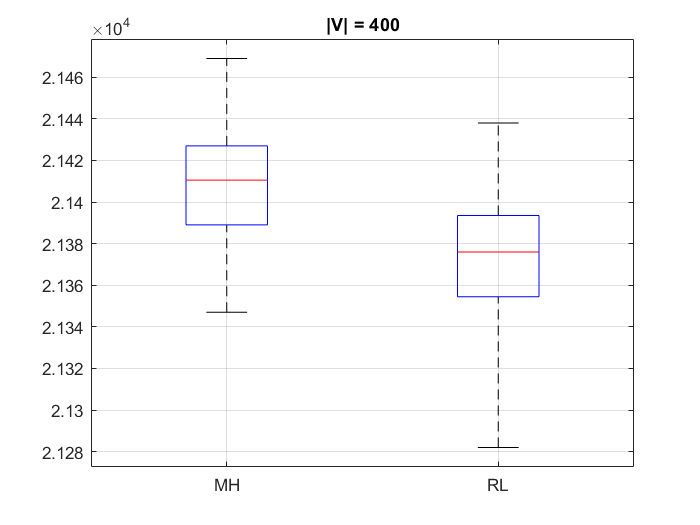


load("sfm_1graphs_400nodes_100runs_1.2e6prop.mat")
min_energies = min_energies * -1;
min_energies_sfm = min_energies;
load("rl_1graphs_400nodes_100runs.mat")
sfm = min_energies_sfm(1,:).';
rl = min_energies(1,:).';
figure
boxplot([sfm rl], 'Labels', {'MH', 'RL'}, 'Whisker',10000)
title('|V| = 400')
grid on

# All sizes plot

line plot comparing performance at all graph sizes

Each point is the summary of 100 graphs of the given size, each graph run 15 trials. All graphs are ER with edge density 0.5. 

Interpret rl as (graph_size, num_trials, graph#) 

Means plotted directly as energy vs nodes does not yield any discernable difference. The difference is only apparent when you plot mean_rl - mean_mcmc, since it is ~3 even for graphs of size 200, where the energy is ~5500. 

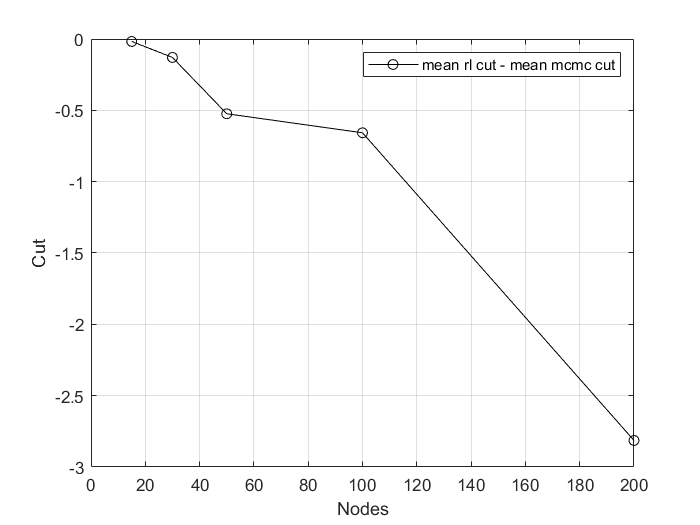

clearvars
nodes = [15, 30, 50, 100, 200];
rl = zeros(5,100,15);
sfm = zeros(5,100,15);
load ("rl_100graphs_15nodes_100runs.mat")
rl(1,:,:) = min_energies(:,1:15);
load ("rl_100graphs_30nodes_15runs.mat")
rl(2,:,:) = min_energies(:,1:15);
load ("rl_100graphs_50nodes_15runs.mat")
rl(3,:,:) = min_energies(:,1:15);
load ("rl_100graphs_100nodes_15runs.mat")
rl(4,:,:) = min_energies(:,1:15);
load ("rl_100graphs_200nodes_15runs.mat")
rl(5,:,:) = min_energies(:,1:15);

load("sfm_100graphs_15nodes_100runs_1e5prop.mat")
min_energies = min_energies * -1;
sfm(1,:,:) = min_energies(:,1:15);
load("sfm_100graphs_30nodes_100runs_1e5prop.mat")
min_energies = min_energies * -1;
sfm(2,:,:) = min_energies(:,1:15);
load("sfm_100graphs_50nodes_100runs_1e5prop.mat")
min_energies = min_energies * -1;
sfm(3,:,:) = min_energies(:,1:15);
load("sfm_100graphs_100nodes_100runs_1e5prop.mat")
min_energies = min_energies * -1;
sfm(4,:,:) = min_energies(:,1:15);
load("sfm_100graphs_200nodes_15runs_1e5prop.mat")
min_energies = min_energies * -1;
sfm(5,:,:) = min_energies(:,1:15);

mean_vals_rl = [];
plus_std_rl = [];
minus_std_rl = [];
min_vals_rl = [];
mean_vals_sfm = [];
plus_std_sfm = [];
minus_std_sfm = [];
min_vals_sfm = [];


sum_mean = zeros(100);
for i=1:5
    min_energies(:,:) = rl(i,:,:);
    mean_vals_rl = mean(min_energies,2);
    plus_std_rl = mean_vals_rl+std(min_energies,0,2);
    minus_std_rl = mean_vals_rl-std(min_energies,0,2);
    max_vals_rl = max(min_energies, [], 2);
    
    min_energies(:,:) = sfm(i,:,:);
    mean_vals_sfm = mean(min_energies,2);
    plus_std_sfm = mean_vals_sfm+std(min_energies,0,2);
    minus_std_sfm = mean_vals_sfm-std(min_energies,0,2);
    max_vals_sfm = max(min_energies, [], 2);
    
    
    overall_mean_vals_sfm(i) = mean(mean_vals_sfm);
    overall_mean_vals_rl(i) = mean(mean_vals_rl);
    
    overall_max_vals_sfm(i) = max(max_vals_sfm);
    overall_max_vals_rl(i) = max(max_vals_rl);
    
end

figure
grid on
hold on
box on
plot(nodes, overall_mean_vals_rl - overall_mean_vals_sfm, 'k-o')
legend 'mean rl cut - mean mcmc cut'
xlabel('Nodes')
ylabel('Cut')
hold off

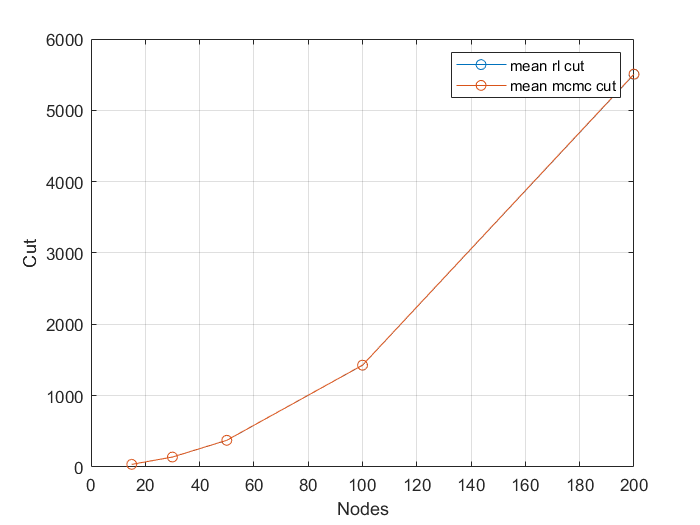


figure
grid on
box on
hold on
plot(nodes, overall_mean_vals_rl,'-o')
plot(nodes, overall_mean_vals_sfm,'-o')
legend ('mean rl cut', 'mean mcmc cut')
xlabel('Nodes')
ylabel('Cut')
hold off